# An explorational test method for learning vehicle control system robustness against sensor noise and MITM attack

### Test environment

The environment is a 14DOF passenger car with different sub components (e.g. Driveline, Engine (SI), vehicle body).

The vehicle is controlled with simulated digital ECUs. The ECUs are fed with sensor signals sampled from the simulation at every 5msec. And controls the vehicle dynamics by actuators with commands at each 5msec. The sensor signals and actuator commands are converted back and forth to fixed point numbers as they were embedded ito CAN frames.

The model used has a test "device" which introduce noise into the wheel speed sensor digital data flow: Each captured "true" wheel speed value is followed by a fake wheel speed sample.

### Vision

The proposed test method explores the stability of the investigated control system, the quality of its sensor signal conditioning algarithms and the its ability to learn external interventions. The proposed method shall find the worst ECU performance by keeping its base operation alive. The test schedule is learnt and can be repetatively used later to evaluate the control algorithm as wel as its infrasructure like signal conditioning and security protection.

### Method

At each controller action phase (at 5 msec sampling) the controller decides if it accepts the signal or refuse its use and stay with the previous state. If the controller accept the sensor value it can be either the true sample or "close" to the true value. Then the expected controller behavior is close to the undisturbed operation i.e. its performance is close to the specification. Similarly if the controller rejects the sensor value and use only the last accepted sample, its performance shall be acceptable. Remember only every second signal is tampered.

### Result

The result shall be a trained actor (test "device") which can be used in  MIL, SIL and HIL to evaluate the controller performance.

## Preparation

addpath("Config")
addpath("Driveline")
addpath("SI")
addpath("Vehicle")

mdl = "PassCarModel_RL_config";
open_system(mdl);

% Fuzzing noise offset in the interval of 
FO_max = 50;
FO_min = 0;

% Fuzzing noise variation in the range of 
FR_max = 20;
FR_min = 0;

% Reward deceleration component
DecelR = 0;
% Reward wheel speed deviation
ODevR = 0;

% agent and environment interaction time periods
Ts = 0.1;

% total episode time
Tf = 20;

The test device is a Reinforcement Learning actor. The actor

- gets its obeservation from the environment as 4 wheel speeds and the vehicle longitudinal speed and

- issue its actions as noises on the wheel speed signals.

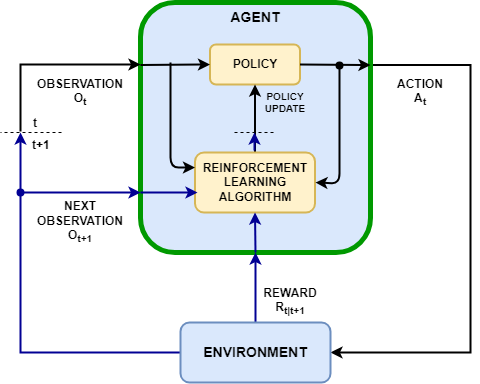

The agent contains two components: a policy and a learning algorithm.

- The policy is a mapping from the current environment observation (wheel speeds and vehicle speed) to a probability distribution of the actions (noise to be injected to the wheel speed signals) to be taken. Within an agent, the policy ("test device") is implemented by a function approximator with tunable parameters and a specific approximation model, such as a deep neural network.

- The learning algorithm continuously updates the policy learnable parameters based on the actions, observations, and rewards. The goal of the learning algorithm is to find an optimal policy that maximizes the expected discounted cumulative long-term reward received during the task.

actionInfo = rlNumericSpec([8 1], 'UpperLimit', [1; 1; 1; 1; 1; 1; 1; 1], 'LowerLimit', [-1; -1; -1; -1; -1; -1; -1; -1]);
obsInfo = rlNumericSpec([5 1]);

env = rlSimulinkEnv(mdl, mdl + "/Agent/RL Agent", obsInfo, actionInfo, 'UseFastRestart', 'on');

env.ResetFcn = @(in)MyResetFunction(in);

Define an agent creation function for batch running

function agent = createSACAgent(obsInfo, actionInfo, Ts)
    agent = rlSACAgent(obsInfo,actionInfo);
    
    agent.UseExplorationPolicy = true;
    
    agent.AgentOptions.ExperienceBufferLength = 1e6;
    agent.AgentOptions.SampleTime = Ts;
    

### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 5.8211s


    agent.AgentOptions.ActorOptimizerOptions.Algorithm = "adam";
    agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-4;
    agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;
    
    for ct = 1:2
        agent.AgentOptions.CriticOptimizerOptions(ct).Algorithm = "adam";
        agent.AgentOptions.CriticOptimizerOptions(ct).LearnRate = 5e-4;
        agent.AgentOptions.CriticOptimizerOptions(ct).GradientThreshold = 1;
    end
    agent.AgentOptions.MiniBatchSize = 64;
end

function storeRngSeed(index)
    % Get the current RNG settings
    rngSettings = rng;
    
    % Extract the seed value
    seedValue = rngSettings.Seed;
    
    % Define the filename
    filename = sprintf('rng_seed_%d.txt', index);    
    
    % Write the seed to the file
    fid = fopen(filename, 'w');
    fprintf(fid, 'Seed: %d\n', seedValue);
    fclose(fid);
end


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 1.4748s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 5.4527s


### Searching for referenced models in model 'PassCarModel_RL_config'.
### Found 3 model reference targets to update.
### Starting serial model reference simulation build.
### Model reference simulation target for Driveline is up to date.
### Model reference simulation target for PassVeh14DOF is up to date.
### Model reference simulation target for SiMappedEngineV is up to date.

Build Summary

0 of 3 models built (3 models already up to date)
Build duration: 0h 0m 5.7058s


The agent is only trained during the ABS braking. Therefore the first part of the maneouvre is not needed, so save the operation point of the start of ABS braking.

agent = createSACAgent(obsInfo, actionInfo, Ts);
% save the operation point at the beginning of ABS braking
simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn,"SaveFinalState","on");
simIn = setModelParameter(simIn,"SaveOperatingPoint","on");
simIn = setModelParameter(simIn,"StopTime","11.7");
simIn = setBlockParameter(simIn, mdl + "/Agent/StoppingCondition", Value="-100");
out = sim(simIn);
pcmOP = out.xFinal;
save("PassCarModel_Final_OperationPoint.mat", "pcmOP");
%setBlockParameter(simIn, mdl + "/StoppingCondition", Value="0.1");

### Batch running

The training is using an emergency braking in a curve. The return of an actoin (noise) is the decreased capability of keeping the turning while decelerating as mumch as possible. The episode reward is the sum of returns during the braking.

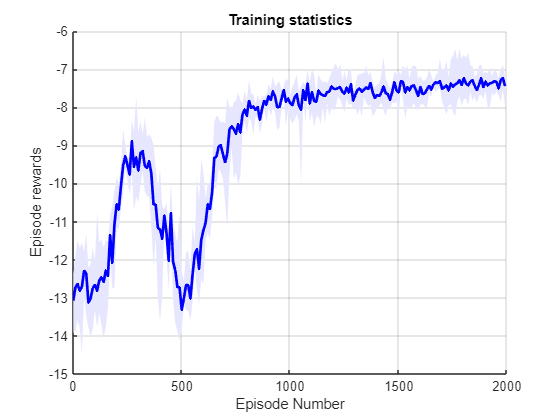

rng("shuffle");
for i = 1:5
    agent = createSACAgent(obsInfo, actionInfo, Ts);
    maxepisodes = 2000;
    maxsteps = ceil(Tf/Ts);
    directory = sprintf('savedAgents_%d', i);
    storeRngSeed(i);

    trainOpts = rlTrainingOptions(...
        MaxEpisodes=maxepisodes,...
        MaxStepsPerEpisode=maxsteps,...
        ScoreAveragingWindowLength=5,...
        Verbose=false,...
        Plots="training-progress",...
        StopTrainingCriteria="EvaluationStatistic",...
        StopTrainingValue=10,...
        SaveAgentCriteria="EvaluationStatistic",...
        SaveAgentDirectory=directory,...
        SaveAgentValue=-12,...
        SimulationStorageType="none");
    
    evaluator = rlEvaluator(NumEpisodes=1,EvaluationFrequency=10);
       
    trainingResults = train(agent, env, trainOpts, Evaluator=evaluator);
    
    filename = sprintf('TrainingResult_%d.mat', i);
    save(filename, "trainingResults");    

    filename = sprintf('Agent_%d.mat', i);
    save(filename, "agent");
end

## Training statistics of batch execution

function es = LoadTrainingResult(trainingResultFile)
    load(trainingResultFile, "trainingResults");
    es = trainingResults.EvaluationStatistic(~isnan(trainingResults.EvaluationStatistic));
end

figure;

es(:, 1) = LoadTrainingResult("savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\TrainingResult_1");
es(:, 2) = LoadTrainingResult("savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\TrainingResult_2");
es(:, 3) = LoadTrainingResult("savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\TrainingResult_3");
es(:, 4) = LoadTrainingResult("savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\TrainingResult_4");
es(:, 5) = LoadTrainingResult("savedAgents\SAC_PassCarModelX_RL_norm_offset_range_cont_4w_lat_batch\TrainingResult_5");

% Compute statistics
meanVals = mean(es, 2);  % Mean across columns
minVals = min(es, [], 2);  % Min across columns
maxVals = max(es, [], 2);  % Max across columns

% Plot
x = 1:2000;
x_sampled = x(1:10:end);

figure;
hold on;

% Shaded area between min and max
fill([x_sampled, fliplr(x_sampled)], [maxVals', fliplr(minVals')], [0.9 0.9 1], 'EdgeColor', 'none');

% Plot mean line
h = plot(x_sampled, meanVals, 'b', 'LineWidth', 2);

xlabel('Row Index');
ylabel('Value');
%title('Mean with Min-Max Band');
%legend('Min-Max Band', 'Mean');
grid on;

hold off;
xlabel('Episode Number');
ylabel('Episode rewards');
title('Training statistics');
f = gcf;
exportgraphics(f, 'SAC_offset_range_cont.pdf', 'ContentType', 'vector');
